# **Simulación 4 Robots**

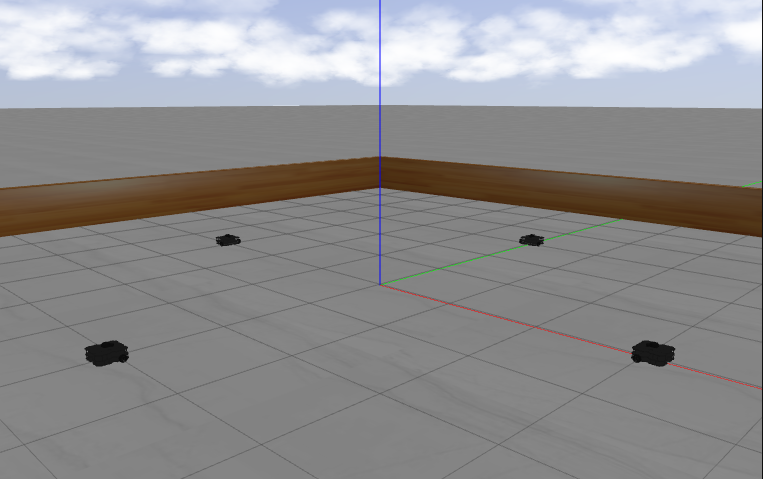

## Simulation 

- Mapa con 4 agentes

% setup enviroment 
clear, clc, close all

Tiempo de Simulación:

% Variables de inicialización
t_sim=30;

Ajuste controlador VFH+ y Pure Pursuit:

%%Inicialización controlador PurePursuit
PP=controllerPurePursuit;
% PP.Waypoints=Way;
PP.MaxAngularVelocity=1.82; %rad/s 
PP.DesiredLinearVelocity=0.2;% m/s
PP.LookaheadDistance=0.5; %m 
%%Inicialización Algoritmo VFH
VFH = controllerVFH;
VFH.UseLidarScan=true;
VFH.NumAngularSectors=360;
VFH.DistanceLimits=[0.3, 3.5];
VFH.RobotRadius=0.22;
VFH.SafetyDistance=0.35;
VFH.MinTurningRadius=0.4;
VFH.HistogramThresholds=[5,10];


Ajuste Algoritmo Flocking:

L=0.5;
thetag=90;
theta=thetag*(pi/180);

Inicialice los waypoints del sistema:

Way1=[-3 0; 3 0];
Way2=[0 3; 0 -3];
Way3=[3 0; -3 0];
Way4=[0 -3; 0 3];

DistanceGoal=0.2;
lim=6;
 




# Ejecutar 

# Four_Robots.slx

Ejecutar al finalizar la ejecución del .slx

%Data robot 1
t1=actuators1.time;
U1=actuators1.signals.values(:,1);
W1=actuators1.signals.values(:,2);
Lidar1.angles=angles1.signals.values;
Lidar1.ranges=ranges1.signals.values;
X1=pose1.signals.values(:,1);
Y1=pose1.signals.values(:,2);
YAW1=pose1.signals.values(:,3);
TD1=targetDir1.signals.values(1,:);
[it_max1,~]=size(Lidar1.ranges);
%Data robot 2
t2=actuators2.time;
U2=actuators2.signals.values(:,1);
W2=actuators2.signals.values(:,2);
Lidar2.angles=angles2.signals.values;
Lidar2.ranges=ranges2.signals.values;
X2=pose2.signals.values(:,1);
Y2=pose2.signals.values(:,2);
YAW2=pose2.signals.values(:,3);
TD2=targetDir2.signals.values(1,:);
[it_max2,~]=size(Lidar2.ranges);
%Data robot 3
t3=actuators3.time;
U3=actuators3.signals.values(:,1);
W3=actuators3.signals.values(:,2);
Lidar3.angles=angles3.signals.values;
Lidar3.ranges=ranges3.signals.values;
X3=pose3.signals.values(:,1);
Y3=pose3.signals.values(:,2);
YAW3=pose3.signals.values(:,3);
TD3=targetDir3.signals.values(1,:);
[it_max3,~]=size(Lidar3.ranges);
%Data robot 4
t4=actuators4.time;
U4=actuators4.signals.values(:,1);
W4=actuators4.signals.values(:,2);
Lidar4.angles=angles4.signals.values;
Lidar4.ranges=ranges4.signals.values;
X4=pose4.signals.values(:,1);
Y4=pose4.signals.values(:,2);
YAW4=pose4.signals.values(:,3);
TD4=targetDir4.signals.values(1,:);
[it_max4,~]=size(Lidar4.ranges);
 

## Graficas

cte=1;
        

### Posiciones:

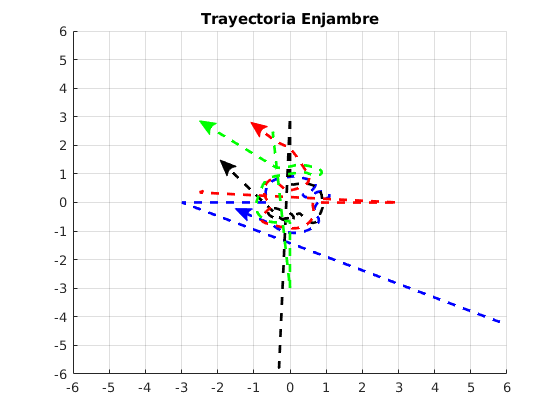

close
figure()
lim=6;
hold on

% plot(Way1(:,1),Way1(:,2),'bd','LineWidth',2);
% plot(Way2(:,1),Way2(:,2),'k+','LineWidth',2);
% plot(Way3(:,1),Way3(:,2),'r*','LineWidth',2);
% plot(Way4(:,1),Way4(:,2),'gs','LineWidth',2);
 xticks(-lim:lim)
 yticks(-lim:lim)
r=0.21;


grid on
xlim([-lim,lim])
ylim([-lim,lim])
title("Trayectoria Enjambre")
%Inicialización robots
% pa1=rectangle('Position',[X1(1)-r Y1(1)-r 2*r 2*r],'Curvature',[1 1],"EdgeColor",'b', ...
%     'FaceColor','b');
plot(X1(1),Y1(1),'b--','LineWidth',2)
% pa2=rectangle('Position',[X2(1)-r Y2(1)-r 2*r 2*r],'Curvature',[1 1],"EdgeColor",'k', ...
%     'FaceColor','k');
plot(X2(1),Y2(1),'k--','LineWidth',2)
% pa3=rectangle('Position',[X3(1)-r Y3(1)-r 2*r 2*r],'Curvature',[1 1],"EdgeColor",'r', ...
%     'FaceColor','r');
plot(X3(1),Y3(1),'r--','LineWidth',2)
% pa4=rectangle('Position',[X4(1)-r Y4(1)-r 2*r 2*r],'Curvature',[1 1],"EdgeColor",'g', ...
%     'FaceColor','g');
plot(X4(1),Y4(1),'g--','LineWidth',2)


ar1=arrow_draw(X1(1),Y1(1),YAW1(1),lim,'b');
ar2=arrow_draw(X2(1),Y2(1),YAW2(1),lim,'k');
ar3=arrow_draw(X3(1),Y3(1),YAW3(1),lim,'r');
ar4=arrow_draw(X4(1),Y4(1),YAW4(1),lim,'g');

% legend("AutoUpdate","off")
% legend("Way1","Way2","Way3","Way4"...
%     ,"Trayectoria1","Trayectoria2","Trayectoria3"...
%     ,"Trayectoria4","Location","bestoutside")
for i=1:(min([length(X1), length(X2),length(X3),length(X4)]))/cte
%     plot(X(i),Y(i),'b>')
%Robot1
%     pos1 = [X1(i)-r Y1(i)-r 2*r 2*r]; 
    delete(ar1);
    plot(X1(1:i),Y1(1:i),'b--','LineWidth',2)
%Robot2    
%     pos2 = [X2(i)-r Y2(i)-r 2*r 2*r]; 
    delete(ar2);
    plot(X2(1:i),Y2(1:i),'k--','LineWidth',2)
%Robot3   
%     pos3 = [X3(i)-r Y3(i)-r 2*r 2*r]; 
    delete(ar3);
    plot(X3(1:i),Y3(1:i),'r--','LineWidth',2)
%Robot4   
%     pos4 = [X4(i)-r Y4(i)-r 2*r 2*r]; 
    delete(ar4);
    plot(X4(1:i),Y4(1:i),'g--','LineWidth',2)
    
    ar1=arrow_draw(X1(i),Y1(i),YAW1(i),lim,'b');
    ar2=arrow_draw(X2(i),Y2(i),YAW2(i),lim,'k');
    ar3=arrow_draw(X3(i),Y3(i),YAW3(i),lim,'r');
    ar4=arrow_draw(X4(i),Y4(i),YAW4(i),lim,'g');
    
%     pa1=rectangle('Position',pos1,'Curvature',[1 1],'FaceColor','b');
%     pa2=rectangle('Position',pos2,'Curvature',[1 1],'FaceColor','k'); 
%     pa3=rectangle('Position',pos3,'Curvature',[1 1],'FaceColor','r');  
%     pa4=rectangle('Position',pos4,'Curvature',[1 1],'FaceColor','g'); 
%     legend("Waypoints","Trayectoria Real")
    pause(0.1)
end 
hold off

### Velocidades:

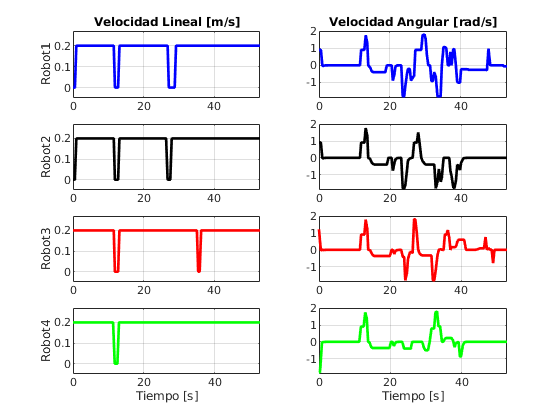

    
figure()
hold on
maxv=0.22;
maxw=1.82;
l1=ones(1,length(t1));
l2=ones(1,length(t2));
l3=ones(1,length(t3));
l4=ones(1,length(t4));
%R1
subplot(4,2,1)
plot(2*t1,U1,'b','LineWidth',2);
hold on
% plot(t1,maxv*l1,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
% plot(t1,-maxv*l1,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
hold off
title("Velocidad Lineal [m/s]")
ylabel("Robot1")
ylim([min(U1)-0.05,maxv+0.05])
xlim([0 2*t1(end)])
grid on
subplot(4,2,2)
plot(2*t1,W1,'b','LineWidth',2);
hold on
% plot(t1,maxw*l1,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
% plot(t1,-maxw*l1,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
hold off
title("Velocidad Angular [rad/s]")
ylim([min(W1)-0.1,maxw+0.2])
xlim([0 2*t1(end)])
grid on
%R2
subplot(4,2,3)
plot(2*t2,U2,'k','LineWidth',2);
hold on
% plot(t2,maxv*l2,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
% plot(t2,-maxv*l2,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
hold off
ylim([min(U2)-0.05,maxv+0.05])
xlim([0 2*t2(end)])
ylabel("Robot2")
grid on
subplot(4,2,4)
plot(2*t2,W2,'k','LineWidth',2);
hold on
% plot(t2,maxw*l2,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
% plot(t2,-maxw*l2,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
hold off
ylim([min(W2)-0.1,maxw+0.2])
xlim([0 2*t2(end)])
grid on
%R3
subplot(4,2,5)
plot(2*t3,U3,'r','LineWidth',2);
hold on
% plot(t3,maxv*l3,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
% plot(t3,-maxv*l3,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
hold off
ylim([min(U3)-0.05,maxv+0.05])
xlim([0 2*t3(end)])
ylabel("Robot3")
grid on
subplot(4,2,6)
plot(2*t3,W3,'r','LineWidth',2);
hold on
% plot(t3,maxw*l3,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
% plot(t3,-maxw*l3,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
hold off
ylim([min(W3)-0.1,maxw+0.2])
xlim([0 2*t3(end)])
grid on
%R4
subplot(4,2,7)
plot(2*t4,U4,'g','LineWidth',2);
hold on
% plot(t4,maxv*l4,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
% plot(t4,-maxv*l4,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
hold off
ylim([min(U4)-0.05,maxv+0.05])
xlim([0 2*t4(end)])
ylabel("Robot4")
xlabel('Tiempo [s]')
grid on
subplot(4,2,8)
plot(2*t4,W4,'g','LineWidth',2);
hold on
% plot(t4,maxw*l4,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
% plot(t4,-maxw*l4,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
hold off
ylim([min(W4)-0.1,maxw+0.2])
xlim([0 2*t4(end)])
xlabel('Tiempo [s]')
grid on

### LIDAR

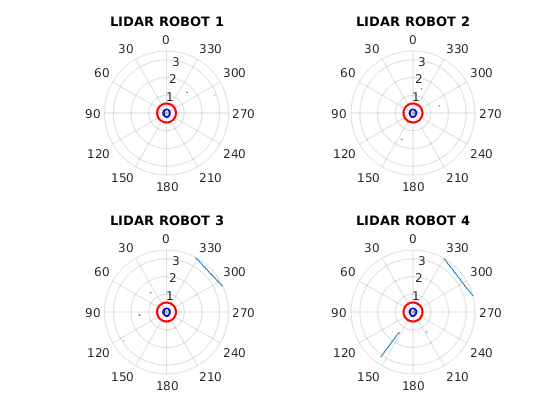

 
% rob=0.5*ones(1,it_max);
RR=VFH.RobotRadius*ones(1,360);
SD=VFH.SafetyDistance+RR;
theta=1:360;
figure
%Robot1
for i=1:(min([it_max1,it_max2,it_max3,it_max4]))/cte
  %Robot 1  
  subplot(2,2,1)
  polarplot(Lidar1.angles(i,:),Lidar1.ranges(i,:))
  ax = gca;
  ax.ThetaZeroLocation = 'top';
  rlim([0 3.5])
  title("LIDAR ROBOT 1")
  hold on
  polarplot(theta,RR,'b')
  polarplot(theta,SD,'r')
  hold off
  %Robot 2  
  subplot(2,2,2)
  polarplot(Lidar2.angles(i,:),Lidar2.ranges(i,:))
  ax = gca;
  ax.ThetaZeroLocation = 'top';
  rlim([0 3.5])
  title("LIDAR ROBOT 2")
  hold on
  polarplot(theta,RR,'b')
  polarplot(theta,SD,'r')
  
  hold off
 %Robot 3  
  subplot(2,2,3)
  polarplot(Lidar3.angles(i,:),Lidar3.ranges(i,:))
  ax = gca;
  ax.ThetaZeroLocation = 'top';
  rlim([0 3.5])
  title("LIDAR ROBOT 3")
  hold on
  polarplot(theta,RR,'b')
  polarplot(theta,SD,'r')
  hold off
 %Robot 4  
  subplot(2,2,4)
  polarplot(Lidar4.angles(i,:),Lidar4.ranges(i,:))
  ax = gca;
  ax.ThetaZeroLocation = 'top';
  rlim([0 3.5])
  title("LIDAR ROBOT 4")
  hold on
  polarplot(theta,RR,'b')
  polarplot(theta,SD,'r')
  hold off
  pause(0.1) 
end

### VFH (Vector Field Histogram):

step=1;

`VFH1:`

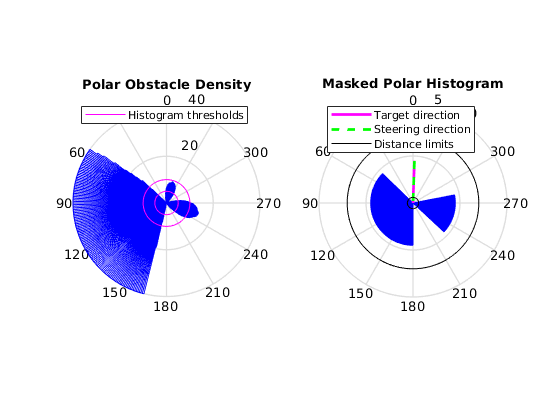

 
for i=1:step:it_max1/cte
%     figure
    scan=lidarScan(Lidar1.ranges(i,:),Lidar1.angles(i,:));
    targetDir =TD1(i);
    VFH(scan,targetDir);
    show(VFH);
    pause(0.1) 
end

`VFH2:`

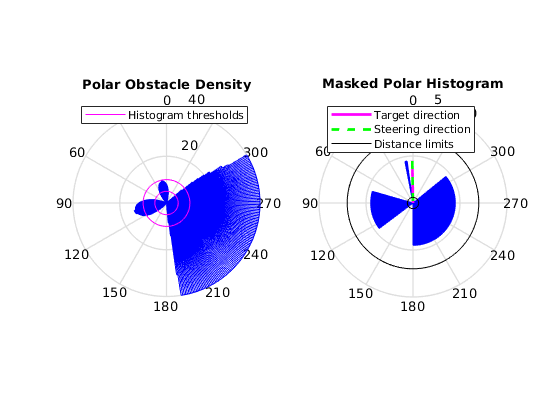

 
for i=1:step:it_max2/cte
%     figure
    scan=lidarScan(Lidar2.ranges(i,:),Lidar2.angles(i,:));
    targetDir =TD2(i);
    VFH(scan,targetDir);
    show(VFH);
    pause(0.1) 
end

`VFH3:`

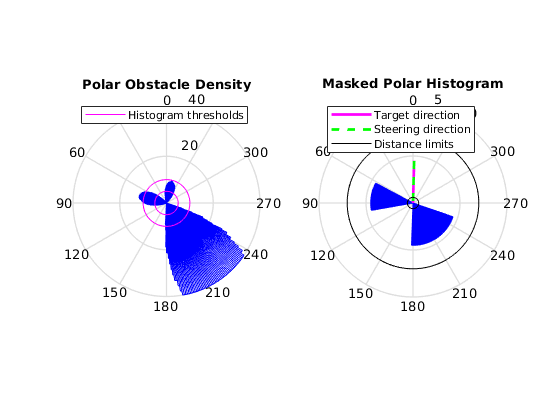

 
for i=1:step:it_max3/cte
%     figure
    scan=lidarScan(Lidar3.ranges(i,:),Lidar3.angles(i,:));
    targetDir =TD3(i);
    VFH(scan,targetDir);
    show(VFH);
    pause(0.1) 
end

`VFH4:`

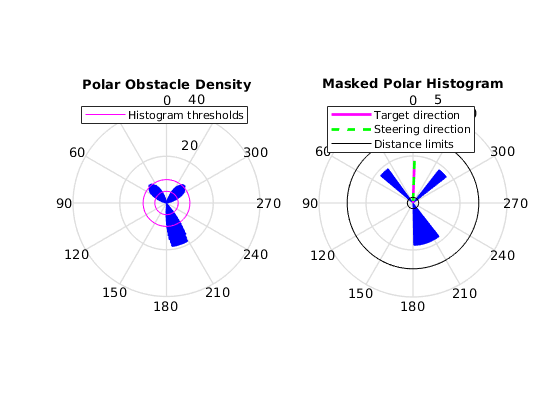

 
for i=1:step:it_max4/cte
    scan=lidarScan(Lidar4.ranges(i,:),Lidar4.angles(i,:));
    targetDir =TD4(i);
    VFH(scan,targetDir);
    show(VFH);
    pause(0.1) 
end